# RVC2: Chapter 3

clear all
close all
clc

## 3.1.2 Transforming spatial velocity

TB = SE3(1, 2, 0) * SE3.Rz(pi/2);

% body to world frame
vb = [0.2 0.3 0 0 0 0.5]';

va = TB.velxform * vb;
va'

ans =    -0.3000    0.2000         0         0         0    0.5000



% same body
TBC = SE3(0, 0.4, 0);
TCB = inv(TBC);
vc = TCB.Ad * vb;
vc'

ans =          0    0.3000         0         0         0    0.5000


## 3.1.3 Incremental rotation

rotx(0.001)

ans =     1.0000         0         0
         0    1.0000   -0.0010
         0    0.0010    1.0000


## 3.2.1 Dynamics of moving bodies

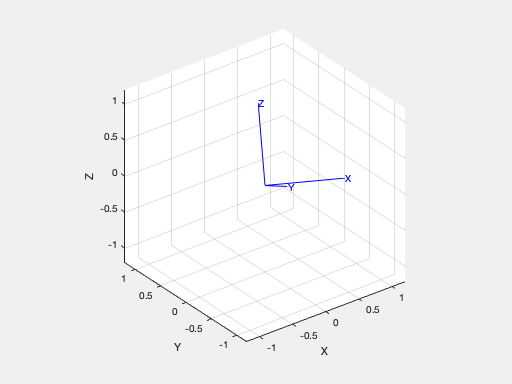

J = [2 -1 0;-1 4 0;0 0 3];
attitude = UnitQuaternion();
w = 0.2*[1 2 2]';
dt = 0.05;
h = attitude.plot();
for t=0:dt:10
   wd =  -inv(J) * (cross(w, J*w));
   w = w + wd*dt;  attitude = attitude .* UnitQuaternion.omega(wd*dt);
   attitude.plot('handle', h); pause(dt)
   end

## 3.2.2 Transforming forces/torques

wrench example

WB = [3 4 0 0 0 0]'

WB =      3
     4
     0
     0
     0
     0


WC = TBC.Ad' * WB;
WC'

ans =     3.0000    4.0000         0         0         0    1.2000


## 3.3 Smooth 1D trajectories

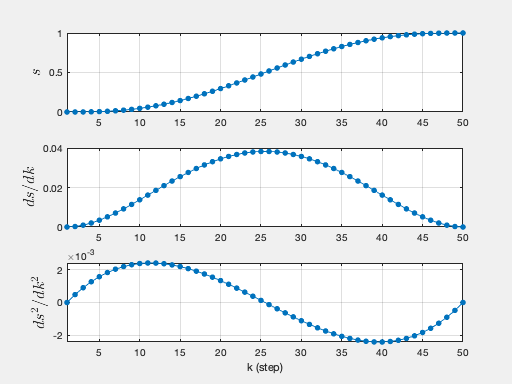

tpoly(0, 1, 50);

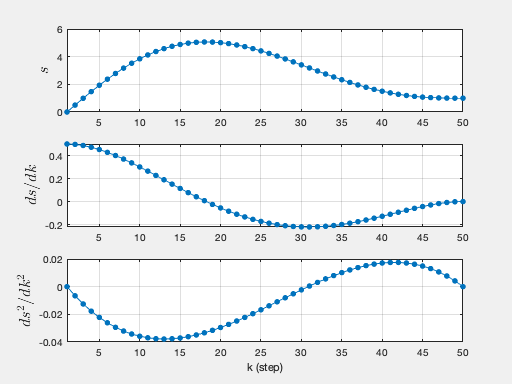

[s,sd,sdd] = tpoly(0, 1, 50);

tpoly(0, 1, 50, 0.5, 0);


mean(sd) / max(sd)

ans = 0.5231

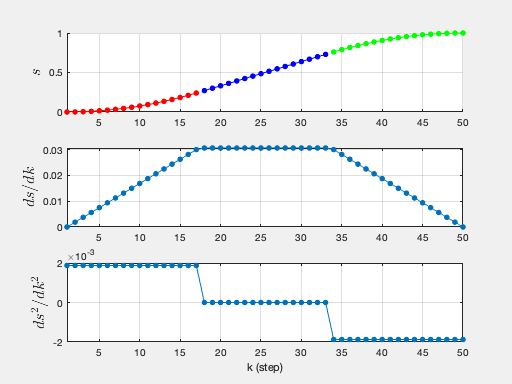



lspb(0, 1, 50);

[s,sd,sdd] = lspb(0, 1, 50);
max(sd)

ans = 0.0306


s = lspb(0, 1, 50, 0.025);
s = lspb(0, 1, 50, 0.035);

## 3.3.2 Multi-dimensional case

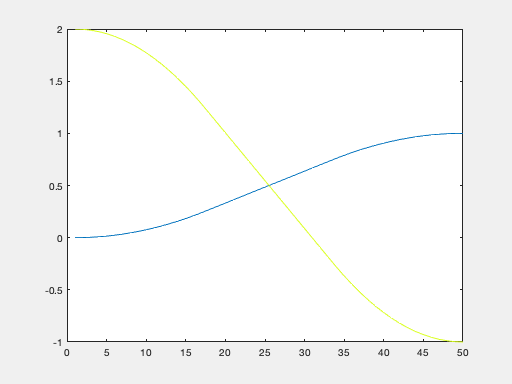

clf
q = mtraj(@lspb, [0 2], [1 -1], 50);
plot(q)

% q = [T1.t' T1.torpy]  % just an example, T1 is not defined

## 3.3.3 Multi-segment trajectoreis

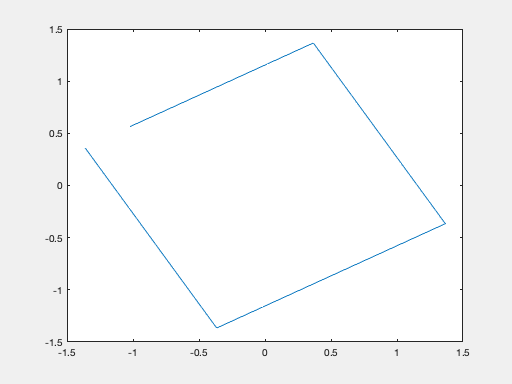

clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
q0 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 0);
plot(q0(:,1), q0(:,2))


q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);

[numrows(q0) numrows(q2)]

ans =     28    80


## 3.3.4 Interpotation of orientation

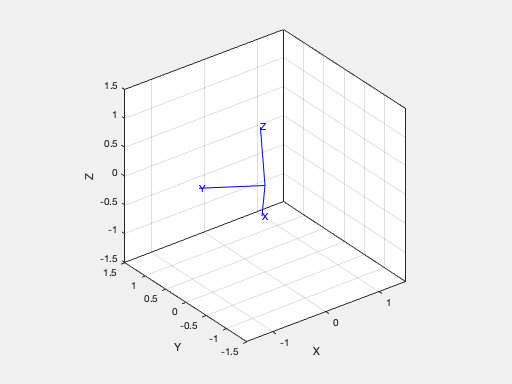

R0 = SO3.Rz(-1) * SO3.Ry(-1);
R1 = SO3.Rz(1) * SO3.Ry(1);

rpy0 = R0.torpy(); rpy1 = R1.torpy();
rpy = mtraj(@tpoly, rpy0, rpy1, 50);
SO3.rpy( rpy ).animate;


q0 = R0. UnitQuaternion;
q1 = R1.UnitQuaternion;

q = interp(q0, q1, 50);
about(q)

q [UnitQuaternion] : 1x50 (1.6 kB)


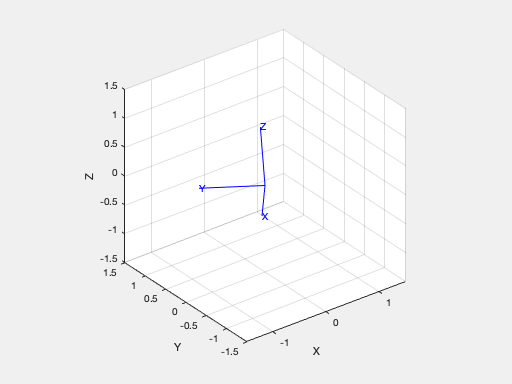

clf
q.animate()

## 3.3.5 Direction of rotation

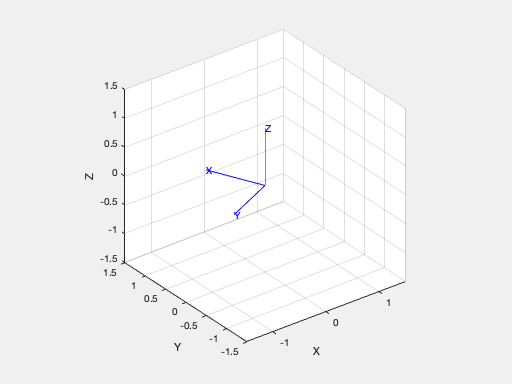

q0 = UnitQuaternion.Rz(-2);
q1 = UnitQuaternion.Rz(2);
q = interp(q0, q1, 50);
q.animate()


q = interp(q0, q1, 50, 'shortest');
q.animate()

## 3.3.6 Cartesian motion

T0 = SE3([0.4, 0.2, 0]) * SE3.rpy(0, 0, 3);
T1 = SE3([-0.4, -0.2, 0.3]) * SE3.rpy(-pi/4, pi/4, -pi/2);


interp(T0, T1, 0.5)

 

ans = 
    0.0975   -0.7020    0.7055         0
    0.7020    0.5510    0.4512         0
   -0.7055    0.4512    0.5465      0.15
         0         0         0         1



Ts = interp(T0, T1, 50);

about(Ts)

Ts [SE3] : 1x50 (6.4 kB)



Ts(1)

 

ans = 
   -0.9900   -0.1411         0       0.4
    0.1411   -0.9900         0       0.2
         0         0         1         0
         0         0         0         1


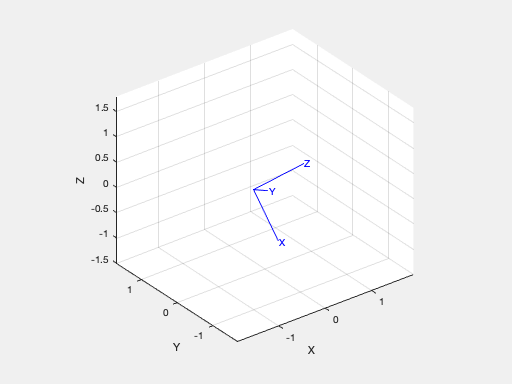


Ts.animate

P = Ts.transl;
about(P)

P [double] : 50x3 (1.2 kB)


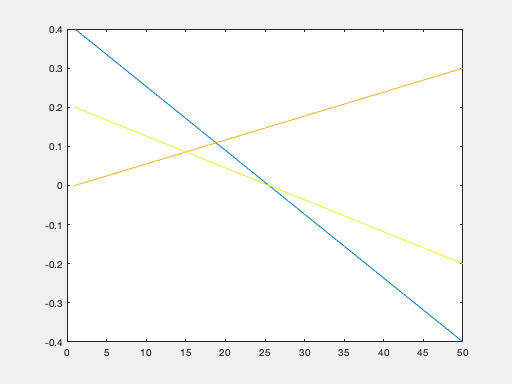

plot(P)

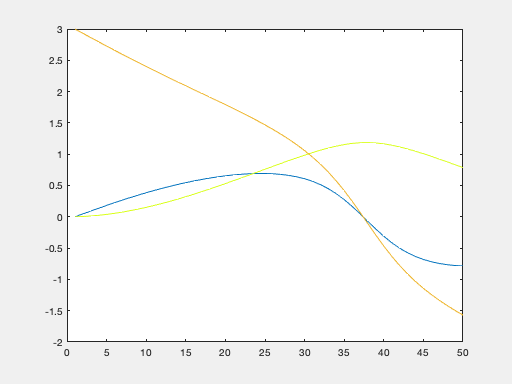


rpy = Ts. torpy;
plot(rpy);



Ts = T0. interp(T1, lspb(0,1, 50) );
Ts = ctraj(T0, T1, 50);

## 3.4.1.2 Estimating orientation

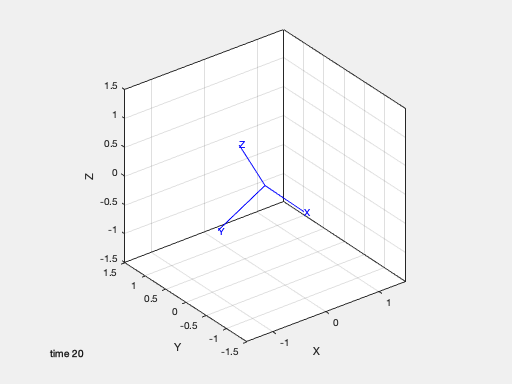

ex_tumble
attitude(1) = UnitQuaternion();
for k=1:numcols(w)-1
   attitude(k+1) = attitude(k) .* UnitQuaternion.omega( w(:,k)*dt );
   end
attitude.animate('time', t)

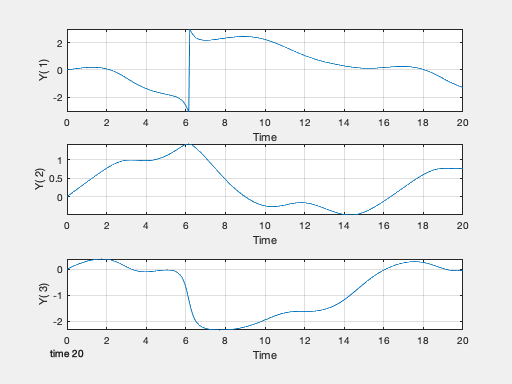

mplot(t, attitude.torpy() )

## 3.4.4 Sensor fusion

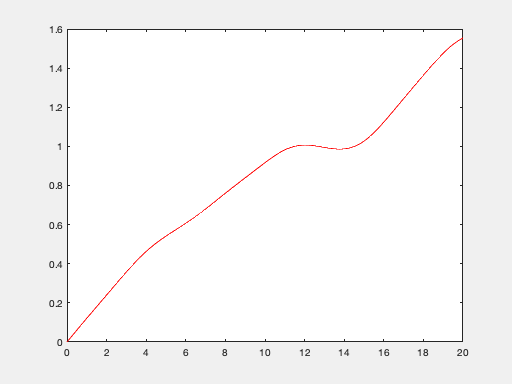

ex_tumble
attitude(1) = UnitQuaternion();
for k=1:numcols(w)-1
   attitude(k+1) = attitude(k) .* UnitQuaternion.omega( wm(:,k)*dt );
   end
clf
plot(t, angle(attitude, truth), 'r' );

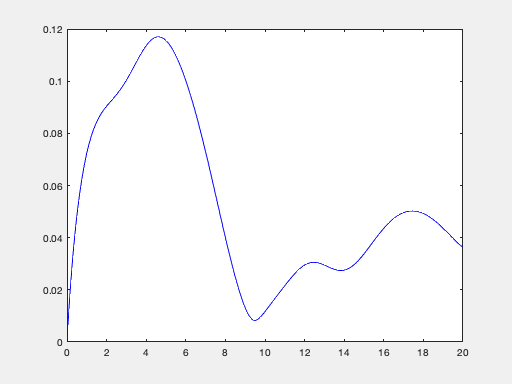



kI = 0.2; kP =1;
b = zeros(3, numcols(w));
attitude_ecf(1) = UnitQuaternion(); b = [0 0 0]';
for k=1:numcols(w)-1
   invq = inv( attitude_ecf(k) );
   sigmaR = cross(gm(:,k), invq*g0) + cross(mm(:,k), invq*m0);
   wp = wm(:,k) - b(:,k) + kP*sigmaR;
   attitude_ecf(k+1) = attitude_ecf(k) .* UnitQuaternion.omega( wp*dt );
   b(:,k+1) = b(:,k) - kI*sigmaR*dt;
   end
plot(t, angle(attitude_ecf, truth), 'b' );